Definicja układu dynamiki:


$$\dot{x}_{1} = x_{1} + x_{2} \\
\dot{x}_{1} = -\frac{x_{1}}{(1 + x_{1}^{2})^{2}} - x_{2} 

$$


syms x1 x2 real

f = [x1 + x2; -x1 / (1 + x1^2)^2 - x2];

Szukamy punkt urównowagi:

xe = solve(f == [0;0], [x1, x2]);
disp("Punkty równowagi:")

Punkty równowagi:


disp(xe)

    x1: 0
    x2: 0



Linearyzacja w każdym punkcie równowagi:

equilibriums_number = length(xe.x1);
A_sym = cell(equilibriums_number, 1);
for index = equilibriums_number
    % Przesunięcie układu współrzędnych
    z1 = x1 - xe.x1(index);
    z2 = x2 - xe.x2(index);
    fz = subs(f, {x1, x2}, {z1, z2});
    % Wyznaczenie macierzy Jakobiego
    A_sym{index} = jacobian(fz, [z1, z2]);
end

Sprawdzenie stabilności dla każdego punktu równowagi:

A_num = cell(equilibriums_number, 1);
for index = equilibriums_number
    % Wyznaczenie numerycznj macierzy Jakobiego
    A = subs(A_sym{index}, {x1, x2}, {xe.x1(index), xe.x2(index)});
    A_num{index} = double(A);
    % Wyznaczenie wartości własnych
    e = eig(A_num{index});
    % Sprawdzenie czy ujemne
    if any(e > 0)
        disp("Punkt równowagi " + index + " jest niestabilny");
    else
        disp("Punkt równowagi " + index + " jest stabilny");
    end
end

Punkt równowagi 1 jest stabilny


Definicja funkcji Lapunowa:


$$V(x) = \frac{x_{1}^{2}}{1 + x_{1}^{2}} + x_{2}^{2}$$


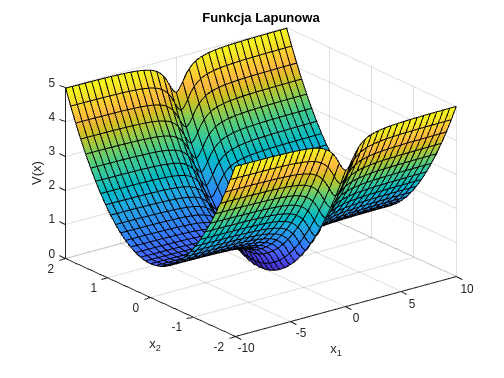

V = x1^2 / (1 + x1^2) + x2^2;
fsurf(V)
xlabel("x_1")
ylabel("x_2")
zlabel("V(x)")
title("Funkcja Lapunowa")


Vp = simplify(gradient(V, [x1, x2])' * f);
disp("Pochodna funkcji Lapunowa")

Pochodna funkcji Lapunowa


disp(Vp)

$$-\frac{2\,\left({x_{1}}^{4}\,{x_{2}}^{2}+2\,{x_{1}}^{2}\,{x_{2}}^{2}-{x_{1}}^{2}+{x_{2}}^{2}\right)}{{\left({x_{1}}^{2}+1\right)}^{2}}$$

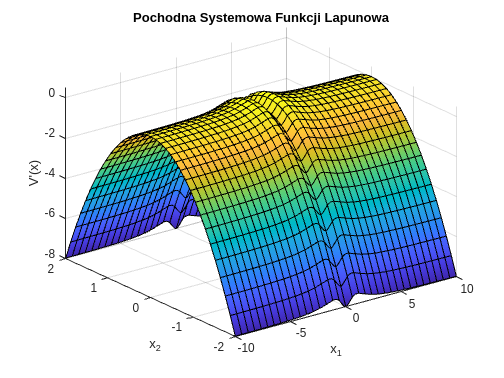

fsurf(Vp)
xlabel("x_1")
ylabel("x_2")
zlabel("V'(x)")
title("Pochodna Systemowa Funkcji Lapunowa")

Sprawdzenie granicy dla $x_{1} \rightarrow \infty$ i $x_{2} = 0$

Vx20 = subs(V, {x2}, {0});
Vlim = limit(Vx20, x1, inf);
disp("Granica dla x1 -> infinity")

Granica dla x1 -> infinity


disp(Vlim)

$$1$$

Wyrysowanie zbiorów poziomicowych:

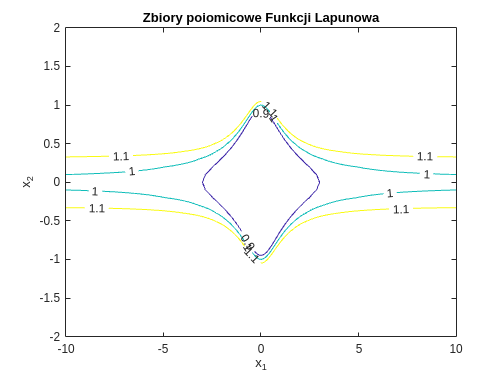

[X1, X2] = meshgrid(-10:0.1:10, -2:0.1:2);
Vnum = X1.^2 ./ (1 + X1.^2) + X2.^2;
contour(X1, X2, Vnum, [0.9, 1, 1.1], "ShowText", "on");
xlabel("x_1")
ylabel("x_2")
title("Zbiory poiomicowe Funkcji Lapunowa")